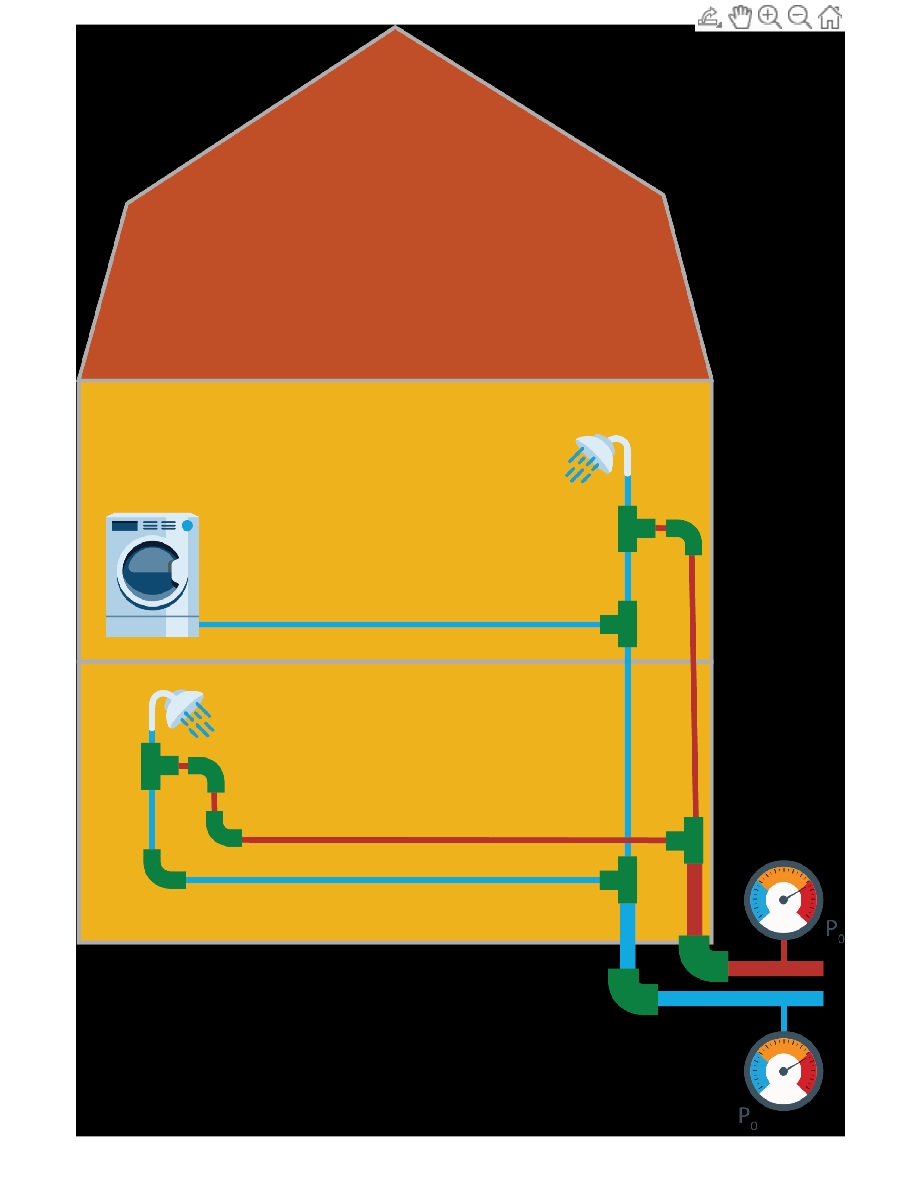

img =   Image with properties:

           CData: [2400×1660×3 uint8]
    CDataMapping: 'direct'

  Show all properties

img = imread("HousePipping.png");
img = imshow(img);
img.ButtonDownFcn = @(src,event)callback(src,event)

function callback(src,event)
    if isempty(src.Parent.UserData)
        src.Parent.UserData = 0;
    end
    src.Parent.UserData = src.Parent.UserData +1;
    disp(src.Parent.UserData)
end